clc

PatientID = 'P1';

% Define the channel pairs to be analyzed
CH_pairs = {'FCz-FC3','FCz-C3','FCz-CP3','CPz-FC3','CPz-C3','CPz-CP3'};

% Select the channel pairs that are available in the dataset
CH_selection = CheckChannelPairs(CH_pairs);

% Process EEG data for a specific participant
ProcessEEGData({PatientID}, CH_selection);

Base Diretory setup for: mac
Pathways defined for use with Mac
Selected channel: FCz -> 39
Selected channel: FC3 -> 38
Selected channel: C3 -> 8
Selected channel: CP3 -> 43
Selected channel: CPz -> 53
******************************************************


Some menu items hidden. Use Preference menu to show them all.
eeglab: options file is ~/eeg_options.m
Retrieving plugin versions from server...
Retrieving download statistics...
EEGLAB: adding "ICLabel" v1.6 (see >> help eegplugin_iclabel)
EEGLAB: adding "clean_rawdata" v2.91 (see >> help eegplugin_clean_rawdata)
EEGLAB: adding "dipfit" v5.4 (see >> help eegplugin_dipfit)
EEGLAB: adding "firfilt" v2.8 (see >> help eegplugin_firfilt)
You are using the latest version of EEGLAB.
pop_loadset(): loading file /Users/muaawiyah/Desktop/Investigation/OwnData/P1RH/P1RH_epochs_filt2_ICAEOG_ERDS.set ...
Reading float file '/Users/muaawiyah/Desktop/Investigation/OwnData/P1RH/P1RH_epochs_filt2_ICAEOG_ERDS.fdt'...
Scaling components to RMS microvolt
Scaling components to RMS microvolt
Creating a new ALLEEG dataset 1
Removing 100 trial(s)...
Pop_select: removing 405 unreferenced events
Scaling components to RMS mi

## Load the selected .mat file


clc
[file, path] = uigetfile('*.mat', 'Select the MATLAB data file');
if isequal(file, 0)
    disp('User canceled the operation');
    return;
end

% Load the selected .mat file
data = load(fullfile(path, file));
disp('.mat Data File Loaded');

.mat Data File Loaded


## Multi-Trial Analysis

% Multi-Trial Analysis for Wrist Extension (WE)
clc;
class_WE = 1;
data_WE = data.data_WE; 
WETable = MultiTrialIDP(data_WE, CH_pairs, CH_selection, 5000, 8000, data.times, class_WE, PatientID);

Combined results table saved to ../OwnResults/P1RH/MatlabGeneratedData/CombinedResults_2024-08-29_15-38-07.mat



% Multi-Trial Analysis for Wrist Flexion (WF)
class_WF = 0;
data_WF = data.data_WF; 
WFTable = MultiTrialIDP(data_WF, CH_pairs, CH_selection, 5000, 8000, data.times, class_WF, PatientID);

Combined results table saved to ../OwnResults/P1RH/MatlabGeneratedData/CombinedResults_2024-08-29_15-38-08.mat



% Generate PLV features for Wrist Extension (WE)
PLVTable_WE = MultiTrialPLV(data_WE, CH_pairs, CH_selection, 5000, 8000, data.times, class_WE, PatientID);

           1        6000

           1        6000

           1        6000

           1        6000

           1        6000

           1        6000

           1        6000

           1        6000

           1        6000

           1        6000

           1        6000

           1        6000

           1        6000

           1        6000

           1        6000

           1        6000

           1        6000

           1        6000

           1        6000

           1        6000

           1        6000

           1        6000

           1        6000

           1        6000

           1        6000

           1        6000

           1        6000

           1        6000

           1        6000

           1        6000

           1        6000

           1        6000

           1        6000

           1        6000

           1        6000

           1        6000

           1        6000

           1        6000

           1


% Generate PLV features for Wrist Flexion (WF)
PLVTable_WF = MultiTrialPLV(data_WF, CH_pairs, CH_selection, 5000, 8000, data.times, class_WF, PatientID);

           1        6000

           1        6000

           1        6000

           1        6000

           1        6000

           1        6000

           1        6000

           1        6000

           1        6000

           1        6000

           1        6000

           1        6000

           1        6000

           1        6000

           1        6000

           1        6000

           1        6000

           1        6000

           1        6000

           1        6000

           1        6000

           1        6000

           1        6000

           1        6000

           1        6000

           1        6000

           1        6000

           1        6000

           1        6000

           1        6000

           1        6000

           1        6000

           1        6000

           1        6000

           1        6000

           1        6000

           1        6000

           1        6000

           1


% Remove the 'Class' column from the PLV tables to avoid duplication
WETable.Class = [];
WFTable.Class = [];

% Combine IDP and PLV features for WE and WF
WETable = [WETable, PLVTable_WE];
WFTable = [WFTable, PLVTable_WF];

% Combine WETable and WFTable vertically to create a 200x19 table (or larger depending on added features)
combinedTable = [WETable; WFTable];

% Display the combined table
disp(combinedTable);

    FCz-FC3-mean    FCz-FC3-std    FCz-FC3-variance    FCz-C3-mean    FCz-C3-std    FCz-C3-variance    FCz-CP3-mean    FCz-CP3-std    FCz-CP3-variance    CPz-FC3-mean    CPz-FC3-std    CPz-FC3-variance    CPz-C3-mean    CPz-C3-std    CPz-C3-variance    CPz-CP3-mean    CPz-CP3-std    CPz-CP3-variance    FCz-FC3    FCz-C3     FCz-CP3    CPz-FC3    CPz-C3     CPz-CP3    Class
    ____________    ___________    ________________    ___________    __________    _______________


% Save the combined table in the appropriate directory
outputDir = fullfile('..', 'OwnResults', [PatientID 'RH'], 'MatlabGeneratedData');

% Create the directory if it doesn't exist
if ~exist(outputDir, 'dir')
    mkdir(outputDir);
end

outputFilename = fullfile(outputDir, ['CombinedWEandWFTable_' datestr(now, 'yyyy-mm-dd_HH-MM-SS') '.mat']);

% Save the combined table to a .mat file
save(outputFilename, 'combinedTable');

fprintf('Combined WE and WF table saved to %s\n', outputFilename);

Combined WE and WF table saved to ../OwnResults/P1RH/MatlabGeneratedData/CombinedWEandWFTable_2024-08-29_15-38-12.mat


## Train & Test split for data


PD = 0.70;  % Percentage for the training set (70%)
rng(1); % Fixed seed for consistent results

% Extract the class labels from the table
labels = combinedTable.Class;

% Create a stratified partition
cv = cvpartition(labels, 'HoldOut', 1 - PD, 'Stratify', true);

% Split the data into training and test sets
Ptrain = combinedTable(training(cv), :);
Ptest = combinedTable(test(cv), :);

% Checking class distribution in the training and test split 
countWF = 0;
countWE = 0;
numRows = height(Ptrain);

for i = 1:numRows
    classValue = Ptrain.Class(i);
    if classValue == 1
        countWE = countWE + 1; 
    elseif classValue == 0
        countWF = countWF + 1; 
    else
        disp(['Unexpected class value at row ', num2str(i)]);
    end
end

disp(['WE Count in Training Set: ', num2str(countWE)]);

WE Count in Training Set: 70


disp(['WF Count in Training Set: ', num2str(countWF)]);

WF Count in Training Set: 70



countWE = 0;
countWF = 0; 

numRows = height(Ptest);

for i = 1:numRows
    classValue = Ptest.Class(i);
    if classValue == 1
        countWE = countWE + 1; 
    elseif classValue == 0
        countWF = countWF + 1; 
    else
        disp(['Unexpected class value at row ', num2str(i)]);
    end
end

disp(['WE Count in Test Set: ', num2str(countWE)]);

WE Count in Test Set: 30


disp(['WF Count in Test Set: ', num2str(countWF)]);

WF Count in Test Set: 30


## Splitting Training & Testing to Independant/Dependant Data


xtrain = Ptrain(:, 1:end-1); % Select all columns except the last one
ytrain = Ptrain.Class; 

xtest = Ptest(:, 1:end-1); 
ytest = Ptest.Class; 


## SVM Training Model

|====================================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   | BoxConstraint|  KernelScale |  Standardize |
|      | result |             | runtime     | (observed)  | (estim.)    |              |              |              |
|====================================================================================================================|
|    1 | Best   |     0.43571 |      1.0687 |     0.43571 |     0.43571 |       1.2263 |       164.28 |         true |
|    2 | Accept |         0.5 |     0.34644 |     0.43571 |     0.44067 |       11.701 |    0.0025948 |        false |
|    3 | Accept |     0.49286 |      0.1234 |     0.43571 |     0.43574 |       157.37 |       3.0743 |        false |
|    4 | Accept |         0.5 |     0.11702 |     0.43571 |     0.43572 |     0.012098 |     0.026368 |         true |
|    5 | Accept |         0.5 |     0.30331 |   

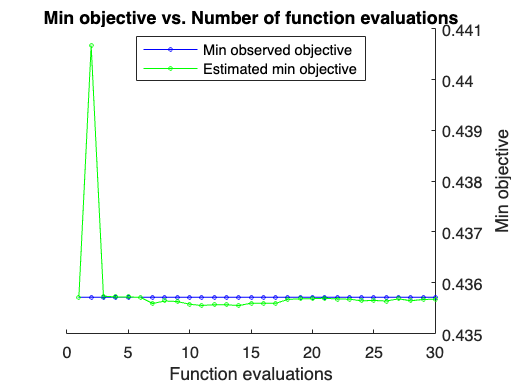


SVMModel = fitcsvm(xtrain, ytrain, 'KernelFunction', 'rbf', 'OptimizeHyperparameters','auto');


% Predict the labels for the training set
yTrainPred = predict(SVMModel, xtrain);

% Calculate the accuracy of the model on the training data
trainAccuracy = sum(yTrainPred == ytrain) / length(ytrain);
disp(['Training Accuracy: ', num2str(trainAccuracy * 100), '%']);

Training Accuracy: 58.5714%



% Predict the labels for the test set
yPred = predict(SVMModel, xtest);

% Calculate the accuracy of the model
testAccuracy = sum(yPred == ytest) / length(ytest);
disp(['Test Accuracy: ', num2str(testAccuracy * 100), '%']);

Test Accuracy: 40%


## Stratified K-Fold Cross Validation

|====================================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   | BoxConstraint|  KernelScale |  Standardize |
|      | result |             | runtime     | (observed)  | (estim.)    |              |              |              |
|====================================================================================================================|
|    1 | Best   |     0.40625 |       0.215 |     0.40625 |     0.40625 |       0.8059 |       0.5335 |        false |
|    2 | Accept |      0.5125 |     0.11372 |     0.40625 |     0.41409 |       348.24 |        471.1 |        false |
|    3 | Accept |         0.5 |     0.15783 |     0.40625 |       0.413 |    0.0053614 |    0.0040261 |         true |
|    4 | Accept |     0.46875 |    0.094133 |     0.40625 |     0.41188 |    0.0013416 |       8.6495 |         true |
|    5 | Accept |     0.43125 |     0.10675 |   

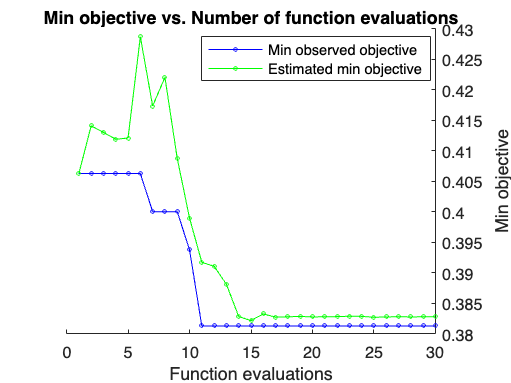

|====================================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   | BoxConstraint|  KernelScale |  Standardize |
|      | result |             | runtime     | (observed)  | (estim.)    |              |              |              |
|====================================================================================================================|
|    1 | Best   |         0.5 |      0.1453 |         0.5 |         0.5 |      0.43881 |     0.004932 |         true |
|    2 | Accept |        0.55 |     0.16735 |         0.5 |     0.50381 |       227.04 |       272.87 |        false |
|    3 | Accept |      0.5375 |     0.10445 |         0.5 |     0.50007 |    0.0016859 |       25.292 |         true |
|    4 | Accept |         0.5 |    0.076432 |         0.5 |     0.50004 |       645.39 |    0.0065288 |        false |
|    5 | Accept |         0.5 |     0.21168 |   

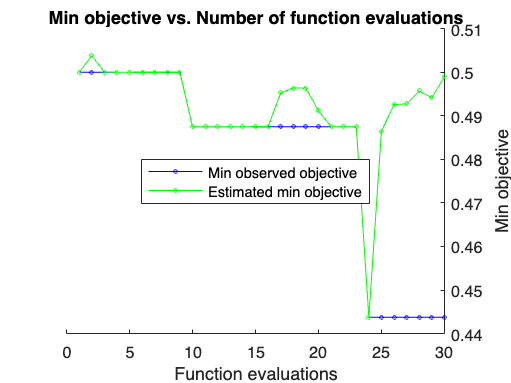

|====================================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   | BoxConstraint|  KernelScale |  Standardize |
|      | result |             | runtime     | (observed)  | (estim.)    |              |              |              |
|====================================================================================================================|
|    1 | Best   |         0.5 |     0.34555 |         0.5 |         0.5 |        94.21 |    0.0066728 |        false |
|    2 | Best   |     0.44375 |     0.12278 |     0.44375 |     0.45265 |       50.333 |       14.078 |         true |
|    3 | Accept |     0.48125 |    0.087552 |     0.44375 |     0.44384 |    0.0034928 |       1.5525 |        false |
|    4 | Accept |         0.5 |    0.093687 |     0.44375 |     0.44685 |    0.0017405 |    0.0056154 |         true |
|    5 | Best   |     0.43125 |    0.080558 |   

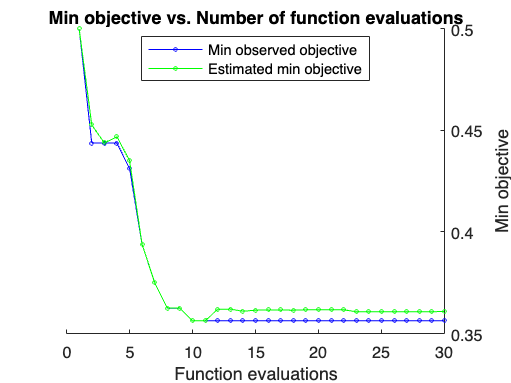

|====================================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   | BoxConstraint|  KernelScale |  Standardize |
|      | result |             | runtime     | (observed)  | (estim.)    |              |              |              |
|====================================================================================================================|
|    1 | Best   |     0.54375 |     0.38091 |     0.54375 |     0.54375 |      0.01973 |       1.9603 |         true |
|    2 | Accept |        0.55 |     0.11732 |     0.54375 |     0.54687 |      0.93163 |        8.811 |        false |
|    3 | Best   |     0.49375 |    0.085048 |     0.49375 |     0.49654 |        109.6 |       11.796 |         true |
|    4 | Accept |         0.5 |    0.083169 |     0.49375 |     0.49375 |       2.3281 |       0.0032 |         true |
|    5 | Accept |        0.55 |    0.074301 |   

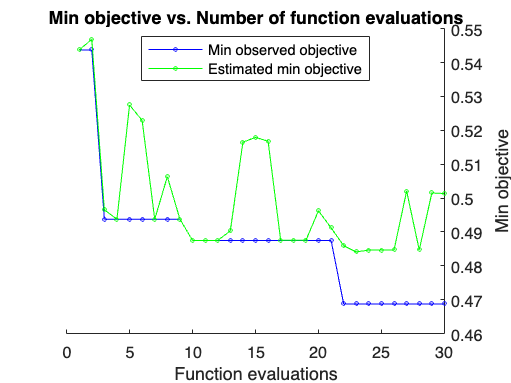

|====================================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   | BoxConstraint|  KernelScale |  Standardize |
|      | result |             | runtime     | (observed)  | (estim.)    |              |              |              |
|====================================================================================================================|
|    1 | Best   |       0.575 |     0.14241 |       0.575 |       0.575 |        247.7 |       68.601 |         true |
|    2 | Best   |         0.5 |    0.082945 |         0.5 |     0.50474 |        964.6 |    0.0057308 |         true |
|    3 | Accept |     0.50625 |    0.089756 |         0.5 |      0.5002 |    0.0060499 |      0.11207 |        false |
|    4 | Best   |      0.4625 |    0.072094 |      0.4625 |      0.4658 |     0.014449 |       3.9236 |         true |
|    5 | Accept |      0.5375 |    0.067397 |   

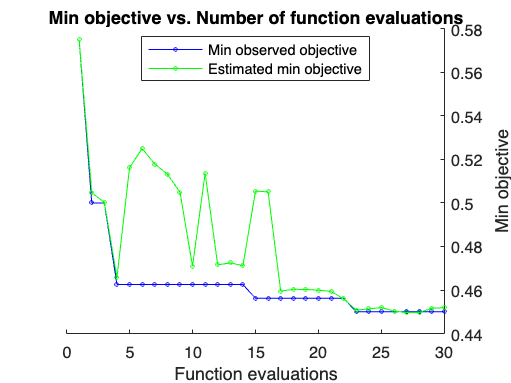


numFolds = 5; % Number of folds for cross-validation

% Use the full combined table for cross-validation
xtrain = combinedTable(:, 1:end-1);
ytrain = combinedTable.Class;

cvPartition = cvpartition(ytrain, 'KFold', numFolds);

foldAccuracy = zeros(numFolds, 1);

for fold = 1:numFolds
    trainIndices = cvPartition.training(fold);
    testIndices = cvPartition.test(fold);

    XtrainFold = xtrain(trainIndices, :);
    YtrainFold = ytrain(trainIndices);
    XtestFold = xtrain(testIndices, :);
    YtestFold = ytrain(testIndices);

    SVMModel = fitcsvm(XtrainFold, YtrainFold, 'KernelFunction', 'rbf', 'OptimizeHyperparameters', 'auto');

    YtestPred = predict(SVMModel, XtestFold);

    foldAccuracy(fold) = sum(YtestPred == YtestFold) / length(YtestFold);
end


meanAccuracy = mean(foldAccuracy);
disp(['Average Cross-Validation Accuracy: ', num2str(meanAccuracy * 100), '%']);

Average Cross-Validation Accuracy: 48%
